# Cubic Polynomial

## Compute polynomials for all joints

### Define variables and values

All values are in joint space. So, if some values are given in cartisian space, the have to be converted: 


$$q = f_r^{-1}(r+dr)
\\
\dot{q} = J^{-1}(q_0)*\dot{p}(0)
\\
\ddot{q} = J^{-1}(q_0)*\ddot{p}(0)$$


n_joints = 2;

% time
T = sym('T');
v = sym('v')

$$v = v$$

T = 0.6226;

% position
q_in_1 = pi/4;
q_in_2 = 0;

q_fin_1 = pi/2;
q_fin_2 = -pi;

q_in =  [q_in_1, q_in_2];
q_fin = [q_fin_1, q_fin_2];

%velocity

%if velocities are in cartisian space q_dot = J^-1 p_dot
v_in_1 = 0;
v_in_2 = 0;

v_fin_1 = 0;
v_fin_2 = 0;

v_in =  [v_in_1, v_in_2];
v_fin = [v_fin_1, v_fin_2];


%acceleration
a_in_1 = (3*pi)/(2*T^2);
a_in_2 = -(pi^3)/(2*T^2);

a_fin_1 = -(3*pi)/(2*T^2);
a_fin_2 = (pi^3)/(2*T^2);

a_in =  [a_in_1, a_in_2];
a_fin = [a_fin_1, a_fin_2];

%matrix of coeffiecients
coeff = zeros(n_joints, 4);

for i=1:n_joints    
    [a,b,c,d] = cubic_poly_function(q_in(i), q_fin(i), v_in(i), v_fin(i), a_in(i), a_fin(i), T, false);
    res = [a,b,c,d];
    display([a,b,c,d])
    for j=1:4
        coeff(i,j) = res(j);
    end
end

$$ans = \left(\begin{array}{cccc} -2 & 3 & 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} -2 & 3 & 0 & 0 \end{array}\right)$$

fprintf('columns: a b c d'); coeff

columns: a b c d

coeff =     -2     3     0     0
    -2     3     0     0


### Compute coefficient joint 1

[a1, b1, c1, d1] = cubic_poly_function(q_in(1), q_fin_1(1), v_in(1), v_fin(1), a_in(1), a_fin(1), T, true);

##############################################################
Cubic Polynomial Double Normalized (tau belongs to [0, 1])

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$

Where Dq = (qfin - qin)
---------------------------------------------------------
Equations:

$$eq\_1 = d=0$$

$$eq\_2 = a+b+c=1$$

$$eq\_3 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$eq\_4 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$

---------------------------------------------------------
Symbolic solutions:

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$d = 0$$

---------------------------------------------------------
Numerical solutions:


$$a = -2$$

$$b = 3$$

$$c = 0$$

$$d = 0$$

##############################################################


### Compute coefficient joint 2

[a2, b2, c2, d2] = cubic_poly_function(q_in_2, q_fin_2, v_in_2, v_fin_2, a_in_2, a_fin_2, T, true);

##############################################################
Cubic Polynomial Double Normalized (tau belongs to [0, 1])

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$

Where Dq = (qfin - qin)
---------------------------------------------------------
Equations:

$$eq\_1 = d=0$$

$$eq\_2 = a+b+c=1$$

$$eq\_3 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$eq\_4 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$

---------------------------------------------------------
Symbolic solutions:

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$d = 0$$

---------------------------------------------------------
Numerical solutions:


$$a = -2$$

$$b = 3$$

$$c = 0$$

$$d = 0$$

##############################################################


## Plots

syms tau;
t = 0:0.01:T;

#### Position plots

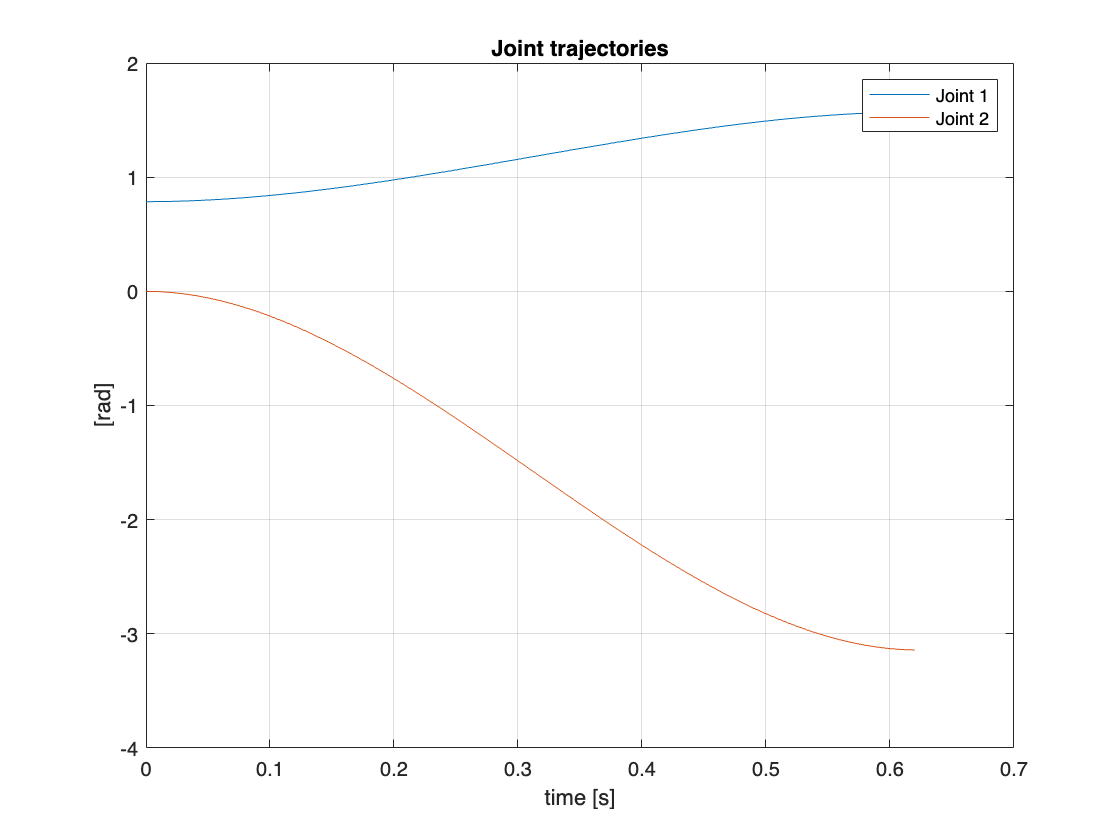

pos_1 = q_in_1 + (q_fin_1-q_in_1) * (d1 + c1*(t/T) + b1*(t/T).^2 + a1*(t/T).^3);
pos_2 = q_in_2 + (q_fin_2-q_in_2) * (d2 + c2*(t/T) + b2*(t/T).^2 + a2*(t/T).^3);

plot(t, pos_1, 'DisplayName', 'Joint 1'); hold on;
plot(t, pos_2, 'DisplayName', 'Joint 2'); hold on;

title('Joint trajectories'); xlabel('time [s]'); ylabel('[rad]'); hold off; legend; grid;

#### Velocities plots

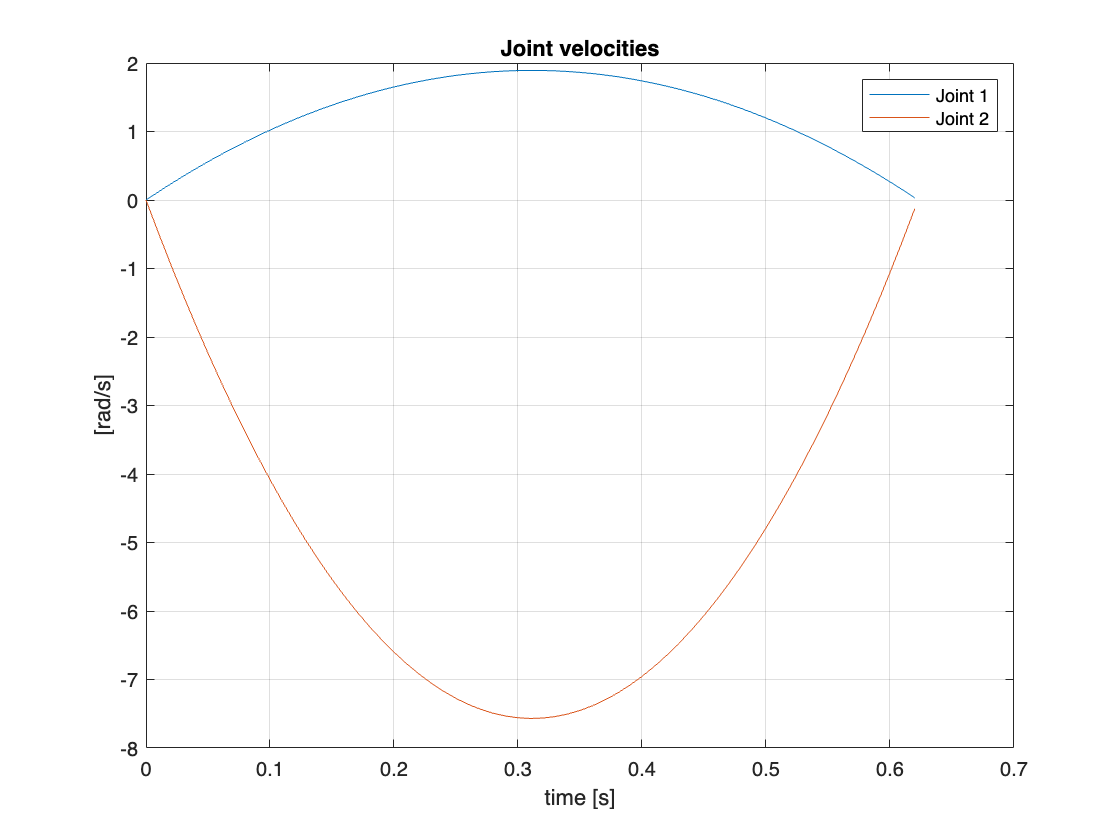

vel_1 = ((q_fin_1-q_in_1)/T) * (c1 + 2*b1*(t/T) + 3*a1*(t/T).^2);
vel_2 = ((q_fin_2-q_in_2)/T) * (c2 + 2*b2*(t/T) + 3*a2*(t/T).^2);

plot(t, vel_1, 'DisplayName', 'Joint 1'); hold on;
plot(t, vel_2, 'DisplayName', 'Joint 2'); hold on;

title('Joint velocities'); xlabel('time [s]'); ylabel('[rad/s]'); hold off; legend; grid;

#### Accelerations plots

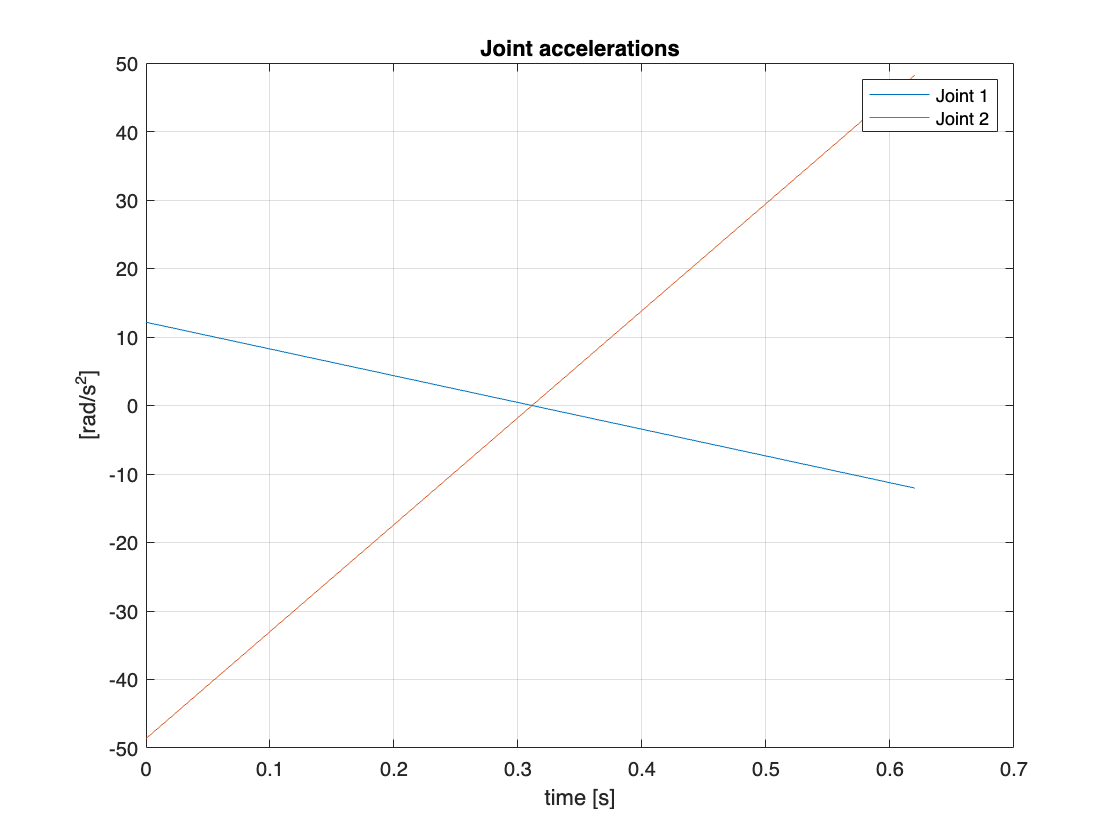

acc_1 = ((q_fin_1-q_in_1)/T^2) * (2*b1 + 6*a1*(t/T));
acc_2 = ((q_fin_2-q_in_2)/T^2) * (2*b2 + 6*a2*(t/T));

plot(t, acc_1, 'DisplayName', 'Joint 1'); hold on;
plot(t, acc_2, 'DisplayName', 'Joint 2'); hold on;
 
title('Joint accelerations'); xlabel('time [s]'); ylabel('[rad/s^2]'); hold off; legend; grid;